clear all; close all
A = [ 4 14 -12;
    0 -4 0;
    1.5 -1 -5];
B = [4; 0; 2];
J = [-1 1.2 3.4;
    -0.25 0.9 0.5;
    -0.85 0.8 2.4];
M = [0; 1; 1];
C = [0 1 0];

C = [C; C; C] %making square matrix out of C 

C =      0     1     0
     0     1     0
     0     1     0



maxval = 1e3; %boudning of cvar and dvar

%LMI variables
Pvar = sdpvar(3,3); %Lyapunov matrix
Zvar = sdpvar(3,3); %defining new indepenten matrices
Qvar = sdpvar(3,3);

ii = 100;           % maximal number of iteration steps
jj = 20;            %max rough bisection steps

high = 100;
low = 1e-3;
Flow_stable = false

Flow_stable = logical
   0


%setting bounds based on expected stability of the solution
if Flow_stable %we have a minimal dwell time d < 0, c > 0
    % Loop parameters cvar
    lb_cvar = low;             % initial value lower search bound
    ub_cvar = high;            % initial value upper search bound
    
else %we have a maximal dwell time d > 0, c < 0
    lb_cvar = -high;             % initial value lower search bound
    ub_cvar = -low;            % initial value upper search bound
end

%
d_cvar = 1e-8;      % maximal difference in cvar between to different iteration steps
d_dvar = 1e-8;      % maximal difference in dvar between to different iteration steps

% Set initial loop values
lbf_cvar = NaN;      % lower bound feasible? NaN: not determined yet, 0: no, 1: yes
ubf_cvar = NaN;      % upper bound feasible? NaN: not determined yet, 0: no, 1: yes

%tracking variables
cvar_track = []


cvar_track =

     []



dvar_track = []


dvar_track =

     []




for i = 1:ii
    %Computing cvar and dvar using bisection
    cvar = bisection(lb_cvar,ub_cvar,lbf_cvar,ubf_cvar);
    
    % Set initial loop values dvar
    lbf_dvar = NaN;      % lower bound feasible? NaN: not determined yet, 0: no, 1: yes
    ubf_dvar = NaN;      % upper bound feasible? NaN: not determined yet, 0: no, 1: yes

    %Resetting bounds dvar
    if Flow_stable
        % Loop parameters dvar
        lb_dvar = -high;             % initial value lower search bound
        ub_dvar= -low;            % initial value upper search bound
    else
        % Loop parameters dvar
        lb_dvar = low;             % initial value lower search bound
        ub_dvar= high;            % initial value upper search bound
    end

    for j=1:jj
        %doing a rough bisection of d to find optimal value
        dvar = bisection(lb_dvar,ub_dvar,lbf_dvar,ubf_dvar);
    
        [Pvar,Qvar,Zvar, L,diagnostics] = LMI_q2b(A,J,cvar,dvar,Pvar,Qvar,Zvar);

        % Check result
        % pres : Primal constraint residuals
        % dres : Dual constraint residuals
        [pres,~] = check(L);
        [ub_dvar, lb_dvar, lbf_dvar, ubf_dvar] = CheckFeasibility(dvar,ub_dvar,lb_dvar,lbf_dvar,ubf_dvar,pres,diagnostics);
        
        dvar_track(i,j) = dvar; %tracking dvar
        if j > 1
            if abs(dvar-dvar_track(i,j-1)) < d_dvar
                break;              % break loop if accurate enough
            end
        end
    end
    
    %determining feasiblity upper or lower bound
    feasibleCvar = 0;
    %setting dvar to the last feasible solution if any 
    if lbf_dvar == 1
        %lowerbound d is feasible, thus cvar is feasible
        feasibleCvar = 1;
    elseif ubf_dvar == 1
        %upperbound d is feasible, thus cvar is feasible
        feasibleCvar = 1;
    end
    [ub_cvar, lb_cvar, lbf_cvar, ubf_cvar] = CheckFeasibilityCvar(cvar,ub_cvar, lb_cvar, lbf_cvar, ubf_cvar,feasibleCvar);
    
    %storing iteration
    cvar_track(i) = cvar;
    if abs(cvar) > maxval
        display('maximal value cvar reached, unbounded problem')
        break
    elseif abs(dvar) > maxval
        display('maximal value cvar reached, unbounded problem')
        break
    end

    if i>1
        if abs(cvar-cvar_track(i-1)) < d_cvar
            break;
        end
    end

    % Store feasible solution
    if feasibleCvar
        feasible.Pvar = Pvar;
        feasible.Qvar = Qvar;
        feasible.Zvar = Zvar;
        feasible.cvar = cvar;
        feasible.dvar = dvar;
    end

end
% Plot iteration history
figure(1)
tiledlayout(1,2)
nexttile
plot(cvar_track,'ro-','LineWidth',2)
xlabel('iteration step')
ylabel('cvar')
title('Iteration results')
grid on
axis tight

nexttile


N = length(cvar_track) %final number of itterations

N = 4

lightBLUE = [0.356862745098039,0.811764705882353,0.956862745098039];
darkBLUE = [0.0196078431372549,0.0745098039215686,0.670588235294118];
 
blueGRADIENTflexible = @(i,N) lightBLUE + (darkBLUE-lightBLUE)*((i-1)/(N-1));

hold on 
for i = 1 :N
    plot(dvar_track(i,:),'color',blueGRADIENTflexible(i,N),'LineWidth',2)
end
xlabel('iteration step')
ylabel('dvar')
title('Iteration results')
ylim()

ans =      0   100


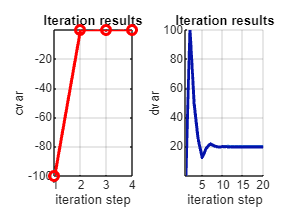

grid on
axis tight


% Retrieve output
P = value(feasible.Pvar)

P =     2.8854   -1.0808   -3.3650
   -1.0808    6.2888    0.8546
   -3.3650    0.8546    7.7923


Q = value(feasible.Qvar)

Q = 1.0e+08 *

    1.7797   -0.0000    0.0000
   -0.0000    1.7797    0.0000
    0.0000    0.0000    1.7797


Z = value(feasible.Zvar)

Z =     0.0775   -0.6803   -1.0165
   -0.6803    5.0902    2.3207
   -1.0165    2.3207    7.8132



L1  = inv(P) * Q  %L1 times C

L1 = 1.0e+08 *

    1.3178    0.1514    0.5525
    0.1514    0.3047    0.0320
    0.5525    0.0320    0.4635


L2 = J - inv(P)* Z  %L2 times C

L2 =    -0.6840    0.5503    1.5297
   -0.1219    0.0448    0.0489
   -0.5971    0.3154    0.6391



c = value(feasible.cvar)

c = -0.0020

d = value(feasible.dvar)

d = 19.7270



dwelltime = abs(d)/abs(c)

dwelltime = 9.8635e+03